# NLMSフィルタ比較

## ステップサイズによる比較

fleng     = 20;     %タップ数

fsize     = 2500;    %フレームサイズ


ssize = 1.8;   %ステップサイズ
lmsfilt1 = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

ssize = 1.5;
lmsfilt2 = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

ssize = 1.2;
lmsfilt3 = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

ssize = 1;
lmsfilt4 = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

## ノイズ

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
dp = Hp()*100;

Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
dw = Hw();

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

xp = firfilt(dp);
xw = firfilt(dw);

TS1 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.1');
TS2 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.05');
TS3 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.001');
TS4 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.0005');
TSe = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

## ホワイトノイズ

% [~,e] = lmsfilt1(dw,xw);
% TS1([xw,e]);
% [~,e] = lmsfilt2(dw,xw);
% TS2([xw,e]);
% [~,e] = lmsfilt3(dw,xw);
% TS3([xw,e]);
% [~,e] = lmsfilt4(dw,xw);
% TS4([xw,e]);

## ピンクノイズ

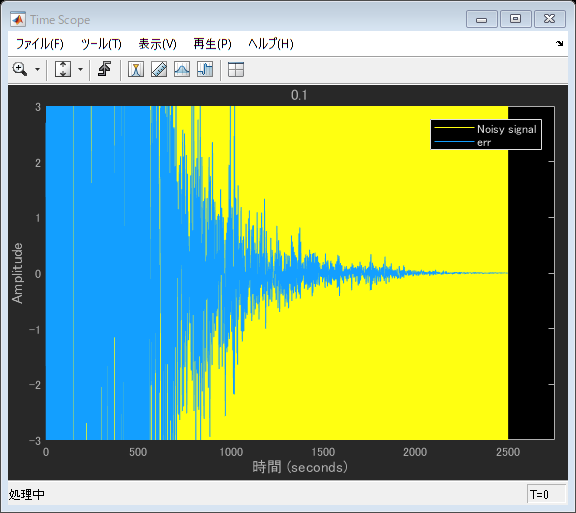

[~,e1] = lmsfilt1(dp,xp);
TS1([xp,e1]);

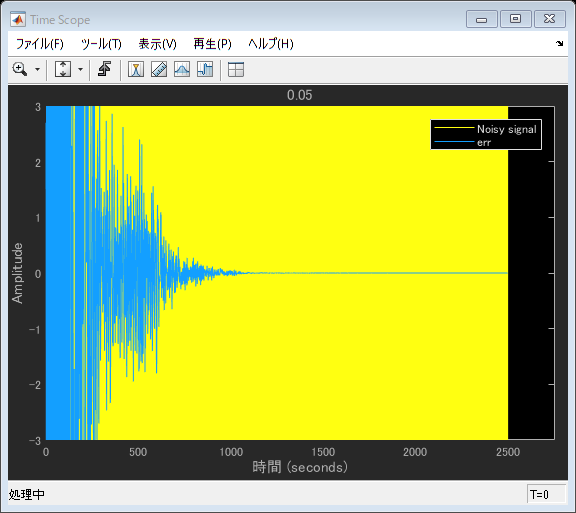

[~,e2] = lmsfilt2(dp,xp);
TS2([xp,e2]);

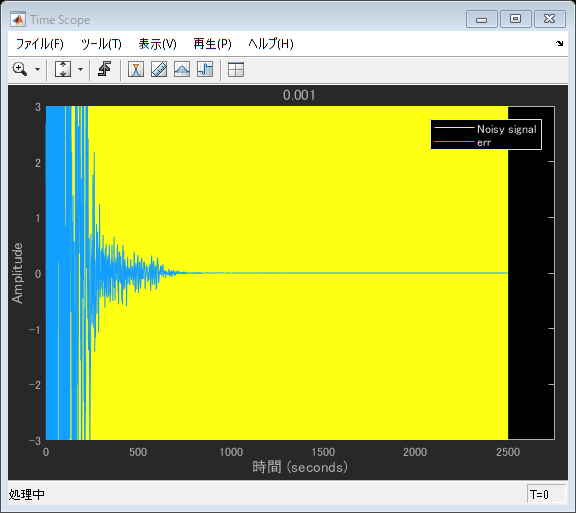

[~,e3] = lmsfilt3(dp,xp);
TS3([xp,e3]);

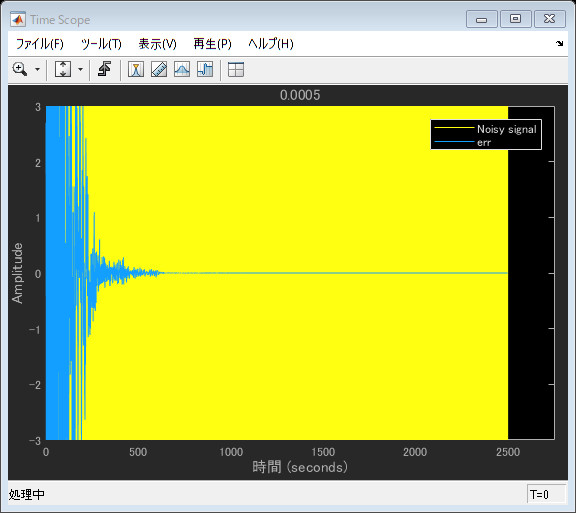

[~,e4] = lmsfilt4(dp,xp);
TS4([xp,e4]);

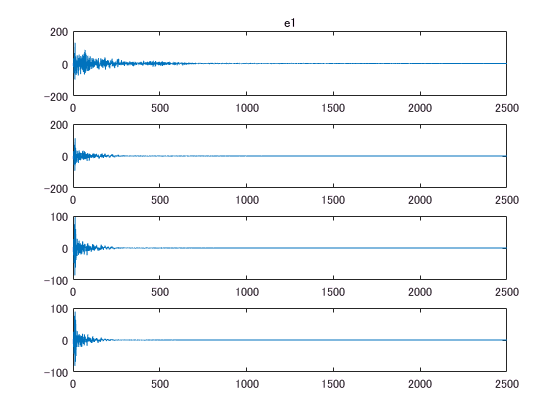


figure
subplot(4,1,1)
plot(e1)
title('e1')
subplot(4,1,2)
plot(e2)
title('e2')
subplot(4,1,3)
plot(e3)
title('e3')
subplot(4,1,4)
plot(e4)

title('e4')